Lecture Notes

A(t,z1) = ifftshift(ifft(exp(-(1j*beta2.*w.^2+alpha)*0.5*z1)...
*fftshift(fft(exp(-1j*z1*gamma*abs(A(t,z0))*abs(A(t,z0)))*A(t,z0)))))

Unrecognized function or variable 'beta2'.

% Do I need fftshift and ifftshift?

% w can be defined in the usual way to avoid needing shifts (0 to N/2, N/2-1 to -1)

% Would A(t,z) at any given moment be my entire signal? Therefore a for loop iterating after a vector of dz steps in space z = [dz1, dz2, dz3 .... , ] with say total length 15km and dz = 500m

## Constants

c=299792458;

% Eventually revert to SI
alpha = 0.2                 % dB/Km
D = 17                      % ps/nm/km
beta_2 = D/0.784            % ps^2/km
gamma = 1.3                 % (km.W)^-1
z = 40                      % Total Fibre Length (km)
dz = 50e-3                  % Spatial Step (km) 




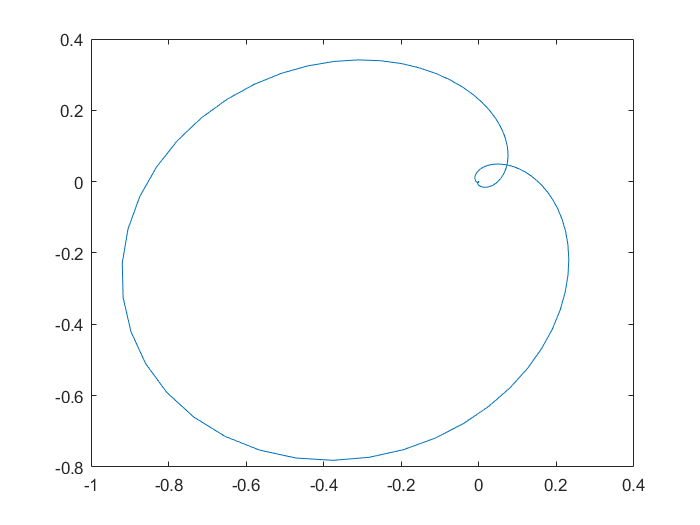

N= 512;
% Number of Fourier modes
dt= .001;
% Time step
tfinal = 10;
% Final time
M= round(tfinal./dt); % Total number of time steps
J= 100;
% Steps between output
L= 50;
% Space period
h= L/N;
% Space step
n=( -N/2:1:N/2-1)';
% Indices
x= n*h;
% Grid points
u= exp(1i*x).*sech(x);%Intial condition
k= 2*n*pi/L;
% Wavenumbers.
for m = 1:1:M
% Start time loop
u= exp(dt*1i*(abs(u).*abs(u))).*u;
% Solve non-linear part of NLSE
c= fftshift(fft(u));
% Take Fourier transform
c = exp(-dt*1i*k.*k/2).*c;
% Advance in Fourier space
u = ifft(fftshift(c));
% Return to Physical Space
end